# Exploring Gibbs Phenomenon

A step change in a signal can be represented as the sum of sine waves, described by the series equation below. 

                    
$$u\left(t\right)\approx \sum_{n\;=\;1}^N \frac{1}{\left(2n-1\right)}\sin \left(\left(2n-1\right)x\right)=\sin \left(x\right)+\frac{1}{3}\sin \left(3x\right)+\frac{1}{5}\sin \left(5x\right)+\frac{1}{7}\sin \left(7x\right)+\;\ldotp \ldotp \ldotp$$


You can see that only the odd terms (1, 3, 5, 7, etc.) contribute to the result. The approximation is more accurate as the number of sine waves, $N$, increases.

    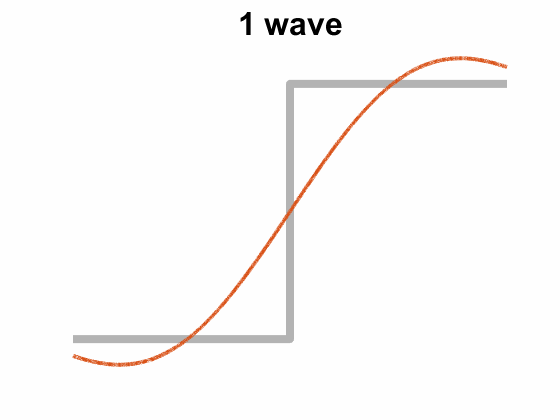

[Gibbs phenomenon](https://en.wikipedia.org/wiki/Gibbs_phenomenon) refers to the overshoot and oscillations that appear at the corners in the approximation. This simple observation has great importance in areas like mathematics, signal processing, acoustics, and optics.

## Task

This exercise will show Gibbs phenomenon by using a for-loop to evaluate the equation above with 20 sine waves. Follow the steps below to do this. 

- Define a new variable `N` with a value of 20.

- Define a new variable `sineSum` equal to `sin(x)`. This is the first term in the equation above. Also, note that `x` has already been defined in the code below.

- Write a for-loop to increment the variable `k` from 3 to `2*N-1`, with increments of 2. When the loop executes, k will have values of 3, 5, 7, up to `2*N-1`.

- Inside the loop, write code to update `sineSum` by adding `1/k*sin(k*x)` to itself. Once the loop is finished, `sineSum` should be the sum of all the sine waves.

- After the loop, add code to create a new plot with `x` on the x-axis and `sineSum` on the y-axis.

**Bonus Activity:  **Once you've successfully completed the problem, try changing the number of sine waves and rerun the code to view the new output. How does the number of waves affect Gibbs phenomenon?

### Setup Code

x = linspace(-1,1,2e4)';

### Code

Task 1 : Define N = 20

N = 20;


Task 2: Create *sineSum *and use a for loop to add odd terms

sineSum = sin(x);   % first term

for k = 3:2:(2*N-1)
    sineSum = sineSum + (1/k)*sin(k*x);
end


Task 3: Plot the Result

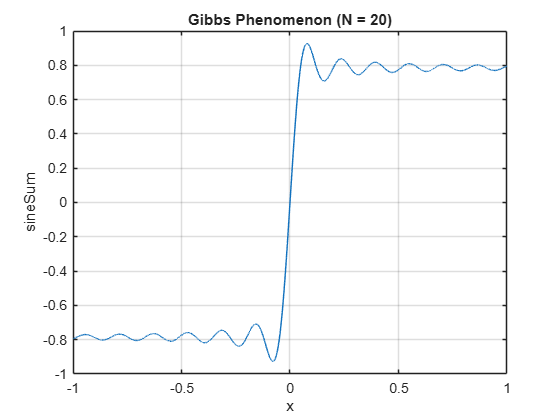

plot(x, sineSum)
xlabel("x")
ylabel("sineSum")
title("Gibbs Phenomenon (N = 20)")
grid on

Bonus Activity : Change N and rerun

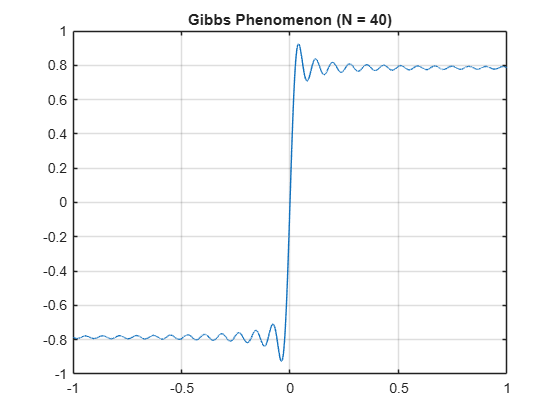

% try 40
N = 40;                
sineSum = sin(x);

for k = 3:2:(2*N-1)
    sineSum = sineSum + (1/k)*sin(k*x);
end

plot(x, sineSum)
title("Gibbs Phenomenon (N = 40)")
grid on

## Check your work

Is your code producing the expected results? 

Compare the values calculated by the code you wrote above to those listed below. Not seeing the output from your code? Remove the semicolons at the end of each line of code and run your code again to see the results.

Hints for common issues are provided below. If you still have questions, consider asking them in the course discussion forum.

**Task 1**

The variable `N` should be equal to 20.

**Task 2**

The variable `sineSum` should be a $20000\times1$ vector containing the sum of the first 20 terms in the series equation given above.

Are your values different? If so, check the following:

- Add code to define the variable `sineSum` to be equal to `sin(x)`.

- Add a [for-loop](https://www.mathworks.com/help/matlab/ref/for.html) to iterate through the values in `3:2:2*N-1`.

- Be sure to add an `end` statement to close the for-loop.

- Inside the loop, add code to update the value of `sineSum` using the equation below where `k` is the loop index variable.

                    
$$\mathrm{sineSum}=\mathrm{sineSum}+\frac{1}{k}\sin \left(kx\right)$$


**Task 3**

`Add` code to generate a [2-D line plot](https://www.mathworks.com/help/matlab/ref/plot.html) with the variable `x` on the x-axis and `sineSum` on the y-axis.

## Conclusion

Congratulations on successfully completing this challenge activity! Continue your learning by returning to the course and marking this challenge complete, as shown in the image below.